clear
clc

load Data.mat


figure
X = mean(net_deltaFC, 1);
Y = mean(net_AFC, 1);

[X, I] = sort(X);
Y = Y(I);

[p, s] = polyfit(X, Y, 1);
x = 0:0.002:0.25;
y = polyval(p, x);
[y_fit,delta] = polyval(p,x,s);

ind = crossvalind('kfold', 5000, 20);

figure
hold on
plot(x,y_fit+2*delta,'m--',x,y_fit-2*delta,'m--')
plot(x, y)
xlabel('\Delta FC', "FontSize", 14)
ylabel('AC', "FontSize", 14)
plot(X(ind == 1), Y(ind == 1), 'd', 'Color', 'black')
ylim([0 0.4])
R = corrcoef(X, Y);
[H, P, CI, STATS] = ttest(mean(net_AFC, 1)', mean(net_deltaFC, 1)')

H = 1

P = 0

CI =     0.0510
    0.0526


STATS = 包含以下字段的 struct :
    tstat: 127.6738
       df: 4999
       sd: 0.0287


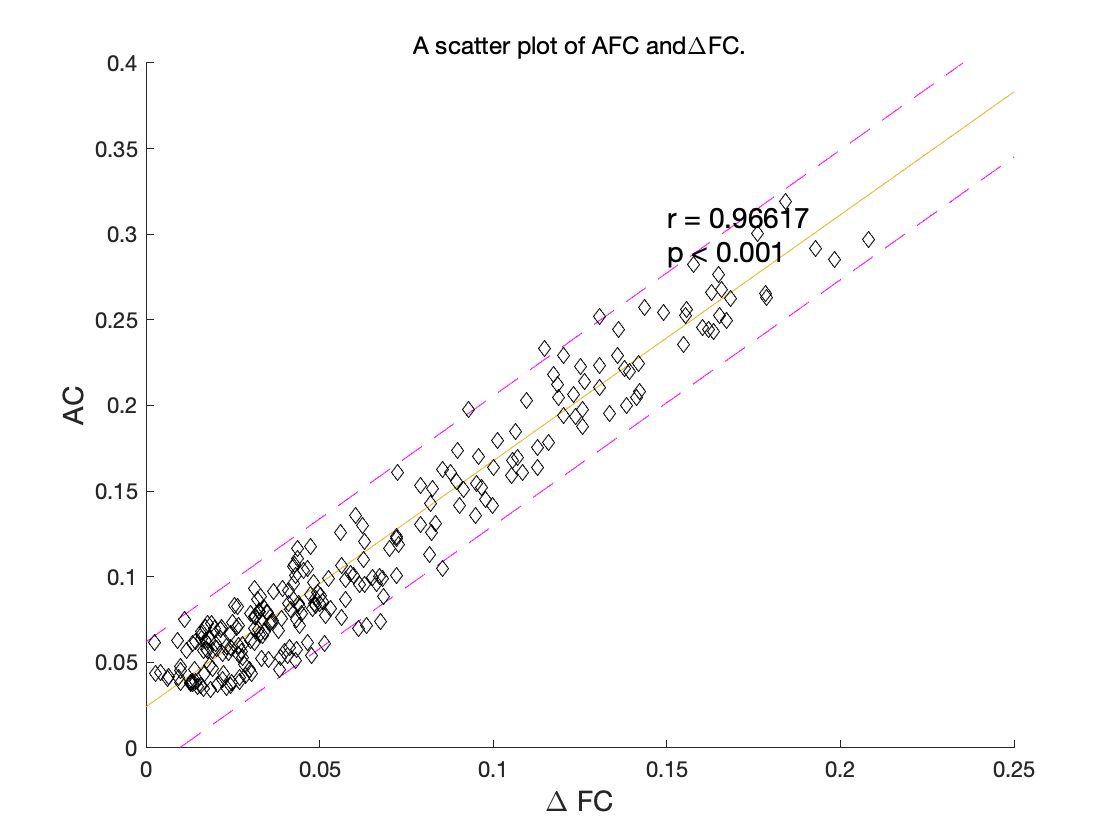

text(0.15, 0.3, {['r = ', num2str(R(1, 2))], 'p < 0.001'}, "FontSize", 14)
title('A scatter plot of AFC and\DeltaFC.')

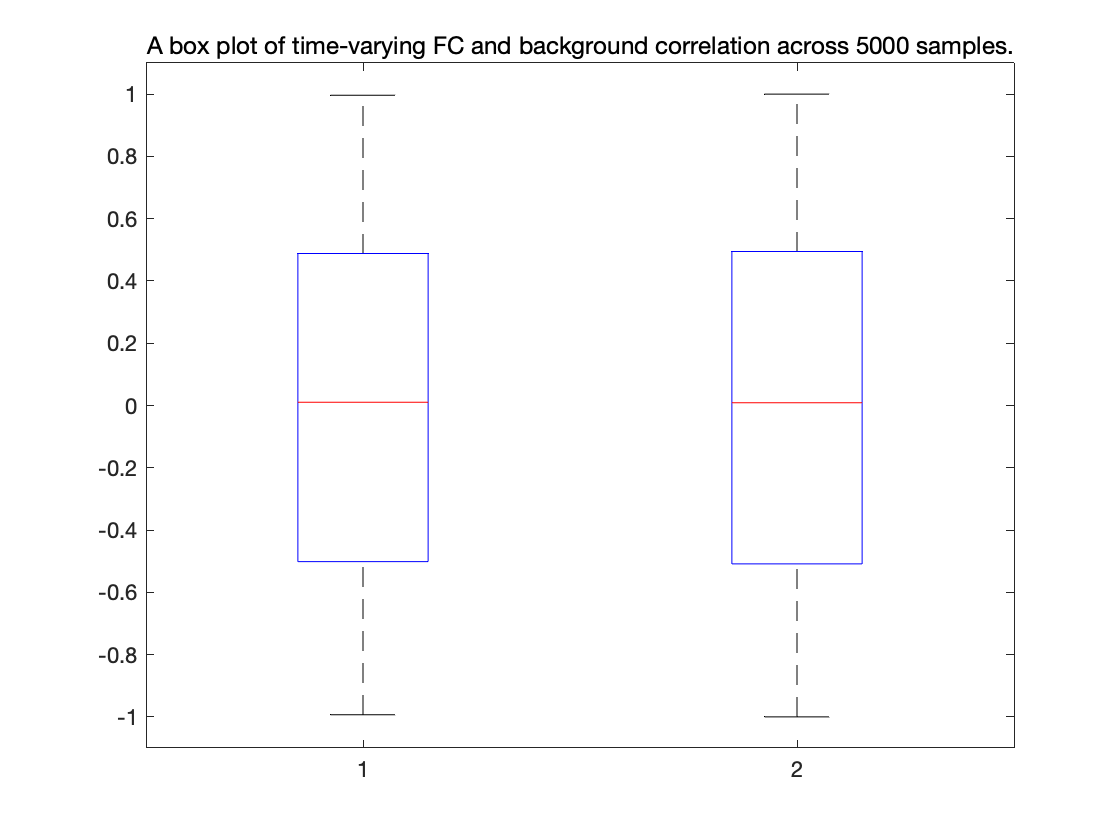

% background & time-varying FC
figure
boxplot([mean(net_TVFC, 1)' mean(net_background, 1)'])
title('A box plot of time-varying FC and background correlation across 5000 samples.')

[H,P,CI,STATS] = ttest(mean(net_TVFC, 1)', mean(net_background, 1)')

H = 0

P = 0.9495

CI = 	1.0e+-3 *

   -0.3210
    0.3009


STATS = 包含以下字段的 struct :
    tstat: -0.0633
       df: 4999
       sd: 0.0112


corrcoef([mean(net_TVFC, 1)' mean(net_background, 1)'])

ans =     1.0000    0.9999
    0.9999    1.0000


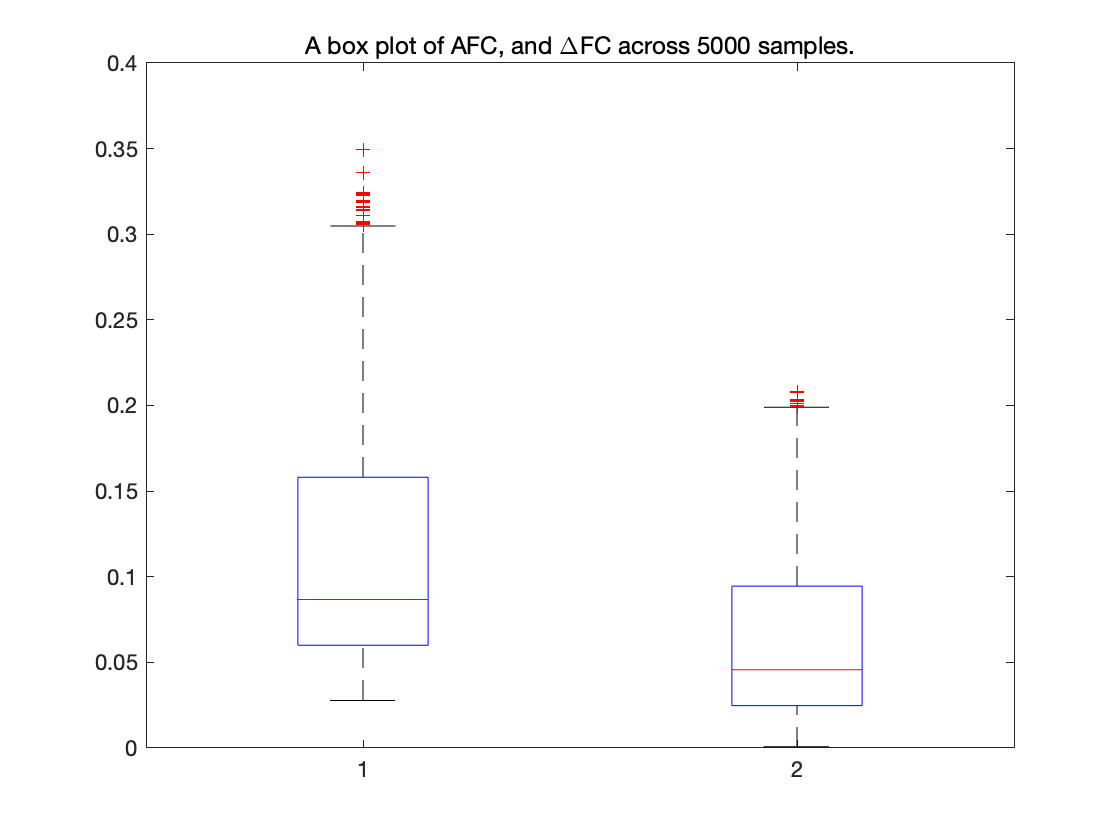


% AFC & \delta FC
figure
boxplot([mean(net_AFC, 1)' mean(net_deltaFC, 1)'])
ylim([0 0.4])
title('A box plot of AFC, and \DeltaFC across 5000 samples.')

[H,P,CI,STATS] = ttest(mean(net_AFC, 1)', mean(net_deltaFC, 1)')

H = 1

P = 0

CI =     0.0510
    0.0526


STATS = 包含以下字段的 struct :
    tstat: 127.6738
       df: 4999
       sd: 0.0287


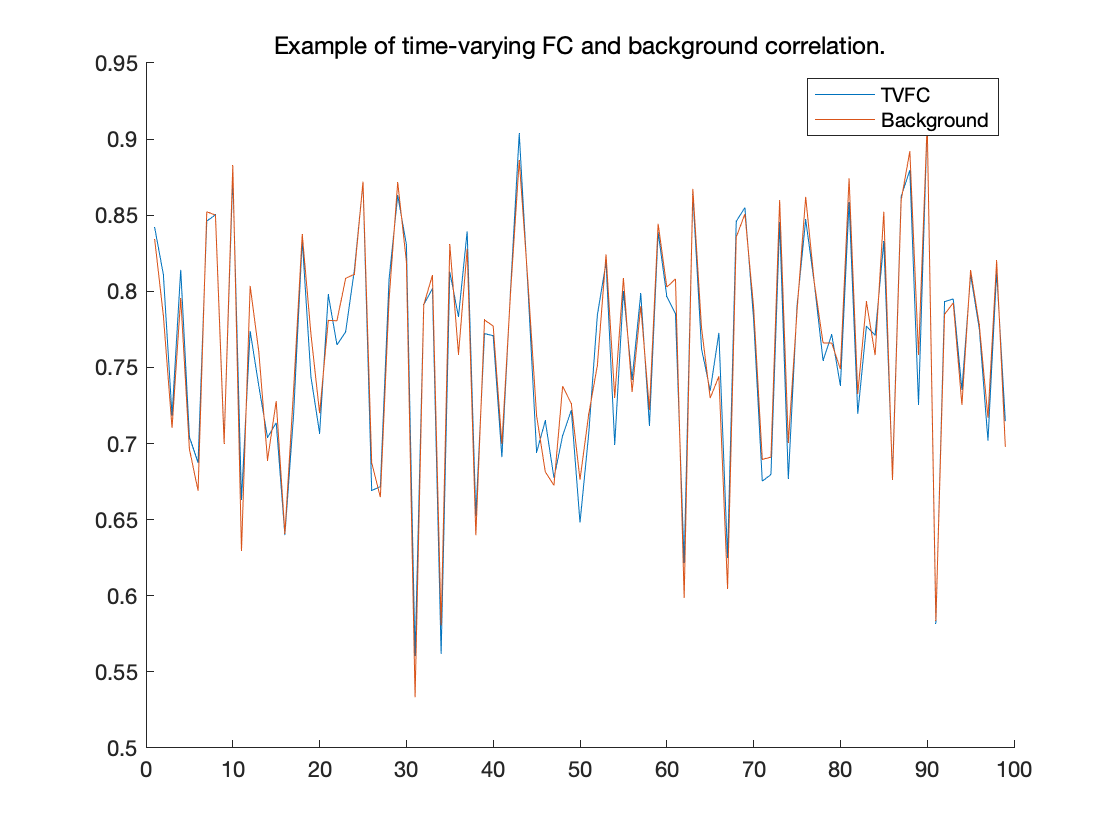




% plot curve TVFC and background correlation
figure
hold on
plot(net_TVFC(:, 1))
plot(net_background(:, 1))
legend('TVFC', 'Background')
title('Example of time-varying FC and background correlation.')